# ======= PARTE 2 - MPC =======

## === Controllo di formazione con guida e Collision Avoidance ===

### Setup, implementazione e analisi MPC

## =====================================================

Autore: [Marina Granozio 607259], Docente: Graziana Cavone

# ===========================

clear all; close all; clc;
set(groot,'defaultFigureRenderer','opengl');
set(0,'DefaultFigureVisible','on');

## ============ SETUP  =============

% Parametri iniziali
A = [1.7 -0.4; 0.4 0.8];
B = [0.2; 0.05];
Q = eye(2);
R = 0.1;

Ts = 0.1;        % Tempo di campionamento
T  = 60;         % Numero di step
N  = 12;         % Orizzonte di predizione
x0 = [2; 1];     % Stato iniziale

% Vincoli sull'ingresso
u_min = -5;
u_max = 5;

% Dimensioni utili
nx = size(A,1);
nu = size(B,2);


## ========= SIMULAZIONE ==========

% Regolazione (u* = 0) 
u_star_reg = 0;
[X, U] = MPC_param(A,B,Ts,T,N,Q,R,u_min,u_max,x0,u_star_reg);
x_ss_reg   = (eye(nx)-A)\(B*u_star_reg);

% Tracking (u* = 5) 
u_star_trk = 5;
[Xtr,Utr]  = MPC_param(A,B,Ts,T,N,Q,R,u_min,u_max,x0,u_star_trk);
x_ss_trk   = (eye(nx)-A)\(B*u_star_trk);

## ====== ANALISI PRESTAZIONI ======

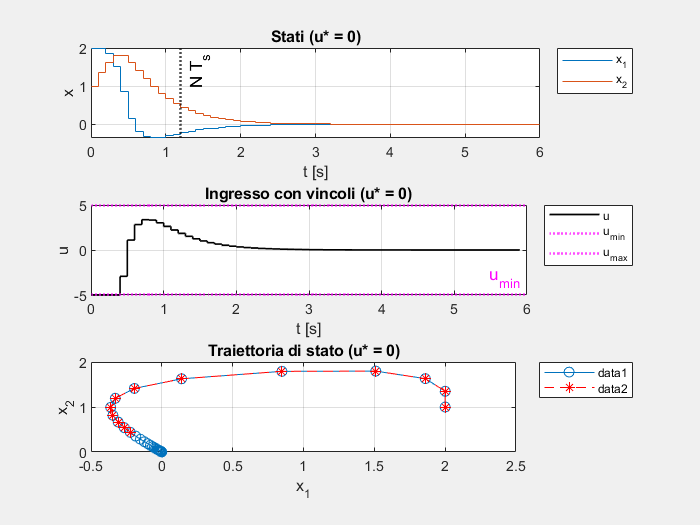

% Tempi
t  = (0:T)*Ts;
tu = (0:T-1)*Ts;

% Regolazione: stati/ingresso/traiettoria 
figure('Name','Regolazione (u*=0)','NumberTitle','off','Visible','on');clf; 
subplot(3,1,1);
stairs(t, X.'); grid on;
xline(N*Ts,':k','N T_s','LineWidth',1.5);
xlabel('t [s]'); ylabel('x'); legend('x_1','x_2','Location','bestoutside','FontSize',7);
title('Stati (u* = 0)');

subplot(3,1,2);
stairs(tu, U.', 'k', 'LineWidth',1); grid on; hold on;
yline(u_min,':m','u_{min}','LineWidth',1.5); yline(u_max,':m','u_{max}','LineWidth',1.5);
xlabel('t [s]'); ylabel('u');
legend('u','u_{min}','u_{max}','Location','bestoutside','FontSize',7);
title('Ingresso con vincoli (u* = 0)');

subplot(3,1,3);
plot(X(1,:), X(2,:), '-o'); grid on; hold on;
plot(X(1,1:N+1), X(2,1:N+1), 'r--*');
xlabel('x_1'); ylabel('x_2');
title('Traiettoria di stato (u* = 0)');; legend('Location','bestoutside','FontSize',7);

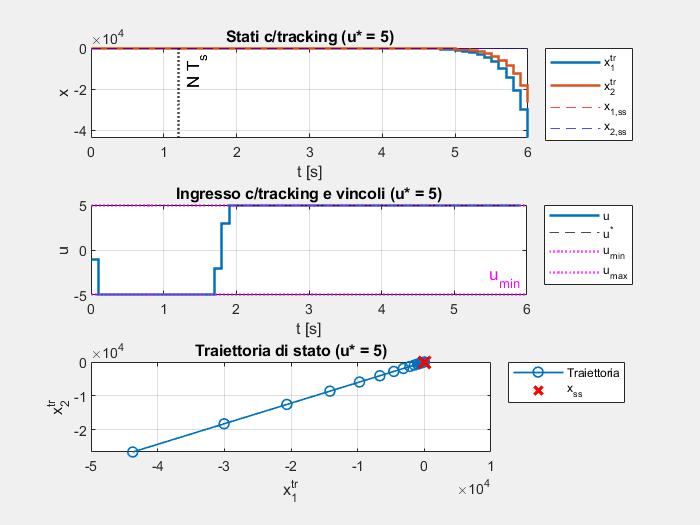

drawnow limitrate;   

% Tracking: stati/ingresso/traiettoria
figure('Name','Tracking (u*=5)','NumberTitle','off','Visible','on');clf;
subplot(3,1,1);
stairs(t, Xtr.', 'LineWidth',1.5); grid on; hold on;
yline(x_ss_trk(1),'--r','x_{1,ss}');
yline(x_ss_trk(2),'--b','x_{2,ss}');
xline(N*Ts,':k','N T_s','LineWidth',1.5);
xlabel('t [s]'); ylabel('x');
legend('x_1^{tr}','x_2^{tr}','x_{1,ss}','x_{2,ss}','Location','bestoutside','FontSize',7);
title('Stati c/tracking (u* = 5)');

subplot(3,1,2);
stairs(tu, Utr.', 'LineWidth',1.5); grid on; hold on;
yline(u_star_trk,'--k','u^*'); yline(u_min,':m','u_{min}', 'LineWidth',1.5); yline(u_max,':m','u_{max}', 'LineWidth',1.5);
xlabel('t [s]'); ylabel('u');
legend('u','u^*','u_{min}','u_{max}','Location','bestoutside','FontSize',7);
title('Ingresso c/tracking e vincoli (u* = 5)');

subplot(3,1,3);
plot(Xtr(1,:), Xtr(2,:), '-o', 'LineWidth',1, 'DisplayName','Traiettoria'); grid on; hold on;
plot(x_ss_trk(1), x_ss_trk(2), 'rx','MarkerSize',10, 'LineWidth',2, 'DisplayName','x_{ss}');
xlabel('x_1^{tr}'); ylabel('x_2^{tr}');
title('Traiettoria di stato (u* = 5)'); legend('Location','bestoutside','FontSize',7);

drawnow limitrate;

## ====== ANALISI: TRE CASI SIGNIFICATIVI ======

cases = [
    struct('N',10, 'Q',5, 'R',0.01, 'tag','(nc) N=10, Q=5I, R=0.01')        % Stati
    struct('N',15, 'Q',1, 'R',0.50, 'tag','(c)  N=15, Q=I, R=0.5')          % Controllo
    struct('N',20, 'Q',1, 'R',0.10, 'tag','(c)  N=20, Q=I, R=0.1')          % Orizzonte
];

Qbase = eye(nx);

% Plot stati & ingresso Reg vs Track
figure('Name','Regolazione vs Tracking (stati/ingressi)','Units','normalized','Position',[0.08 0.1 0.84 0.7]);clf;
nCases = numel(cases);

for i = 1:nCases
        Ni = cases(i).N;
        Qi = cases(i).Q * Qbase;
        Ri = cases(i).R;
    
        [Xr,Ur] = MPC_param(A,B,Ts,T,Ni,Qi,Ri,u_min,u_max,x0,u_star_reg);
        [Xt,Ut] = MPC_param(A,B,Ts,T,Ni,Qi,Ri,u_min,u_max,x0,u_star_trk);   
        
          % Stati
        ax = subplot(3, nCases,i); grid(ax,'on'); hold(ax,'on');
        stairs(ax, t, Xr.', 'LineWidth',1);
        stairs(ax, t, Xt.', '--', 'LineWidth',1);
        xline(ax, Ni*Ts, ':k', 'N T_s','LineWidth',1);
        title(ax, ['Stati  ' cases(i).tag], 'FontSize',7);
        xlabel(ax, 't [s]'); ylabel(ax, 'x');
        %legend(ax, 'x_1 reg','x_2 reg','x_1 tr','x_2 tr','Location','best','FontSize',7);

         % Ingresso
        ax = subplot(3, nCases, nCases + i); grid(ax,'on'); hold(ax,'on');
        stairs(ax, tu, Ur.', 'LineWidth',1);
        stairs(ax, tu, Ut.', '--', 'LineWidth',1);
        yline(ax, u_min, ':m', 'u_{min}', 'LineWidth',1.5); yline(ax, u_max, ':m', 'u_{max}', 'LineWidth',1.5);
        title(ax, ['Ingresso  ' cases(i).tag], 'FontSize',7);
        xlabel(ax, 't [s]'); ylabel(ax, 'u');
        %legend(ax, 'u reg','u tr','u_{min}','u_{max}','Location','best','FontSize',7);

         % Traiettoria
        ax = subplot(3, nCases, 2*nCases + i); grid(ax,'on'); hold(ax,'on');
        plot(ax, Xr(1,:), Xr(2,:), '--',  'LineWidth',1.5);                        % Regolazione
        plot(ax, Xt(1,:), Xt(2,:), '-', 'LineWidth',1);                            % Tracking
        plot(ax, x_ss_trk(1), x_ss_trk(2), 'rx', 'MarkerSize',8, 'LineWidth',1.5); % x_ss Tracking
        title(ax, ['Traiettoria  ' cases(i).tag], 'FontSize',7);
        xlabel(ax, 'x_1'); ylabel(ax, 'x_2');
        %legend(ax, 'reg','track','x_{ss}','Location','best','FontSize',7);
end
drawnow limitrate;